%v = VideoWriter('peaks.avi');
%open(v);

ステップ目標値

x = linspace(-1,10,1000);
for i = 1:1000
    if x(i)<0
y(i) = 0;
    else
        y(i)=1;
    end
end
plot(x,y)
hold on


制御対象 P(s) = 1/(s^2+3s+2) * 1/(0.01s+1)


P1 = tf([-2 2],[1 3 2])*tf(1,[0.01 1]);


PI制御器 K

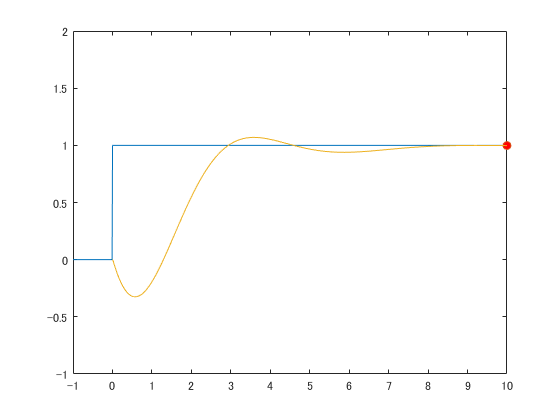

%ゲイン例 K = 0.62, I = 0.43 -> enorm = 1.5343　（スライダーを調整して制御器設計）
K = tf([0.62 0.43],[1 0]);

G = feedback(P1*K,1);

t = 0:0.01:10;

[yout,tout] = step(G,t);

hold on


p = plot(tout(1),yout(1),'o','MarkerFaceColor','red');
hold on
axis([-1 10 -1 2])

for k = 2:length(tout)
    p.XData = tout(k);
    p.YData = yout(k);
    %frame = getframe(gcf);
    %writeVideo(v,frame);
    drawnow
end

plot(tout,yout);

誤差の2ノルム (小さいほうがよい)

minreal((1-G)*tf(1,[1 0]));
enorm = norm(ans,2)

enorm = 1.5343


%frame = getframe(gcf);
%writeVideo(v,frame);

%close(v);

制御器をPIDに限らなければ解析的な誤差2ノルムの下限値は1.4142です。これに近いほど良い制御器と言えます。